# Example 6.5: Images as Matrices

Note: this script reproduces Example 6.5 (Section 6.2) of **Statistics for Chemical Engineers**: a 2D field seen as a matrix, and its rank-1 approximation with and without noise. Victor Z UW-Madison, 2020 images are matrices

clc;  clear all; close all hidden; format short;

## Field

specify mean and covariance

mu = [0 0];
Sigma = [1 0; 0 1]; % nocorrelation

% evaluate probability density function in domain(-3,3 and -3,3)
nmesh = 10;
x1 = linspace(-3,3,nmesh); x2 = linspace(-3,3,nmesh); 
[X1,X2] = meshgrid(x1,x2); % create mesh
F = mvnpdf([X1(:) X2(:)],mu,Sigma); % pdf on mesh
F = 100*reshape(F,length(x2),length(x1));
Fc=uint8(F)

Fc = 10×10 uint8 matrix
    0    0    0    0    0    0    0    0    0    0
    0    0    0    1    1    1    1    0    0    0
    0    0    1    2    4    4    2    1    0    0
    0    1    2    6    9    9    6    2    1    0
    0    1    4    9   14   14    9    4    1    0
    0    1    4    9   14   14    9    4    1    0
    0    1    2    6    9    9    6    2    1    0
    0    0    1    2    4    4    2    1    0    0
    0    0    0    1    1    1    1    0    0    0
    0    0    0    0    0    0    0    0    0    0


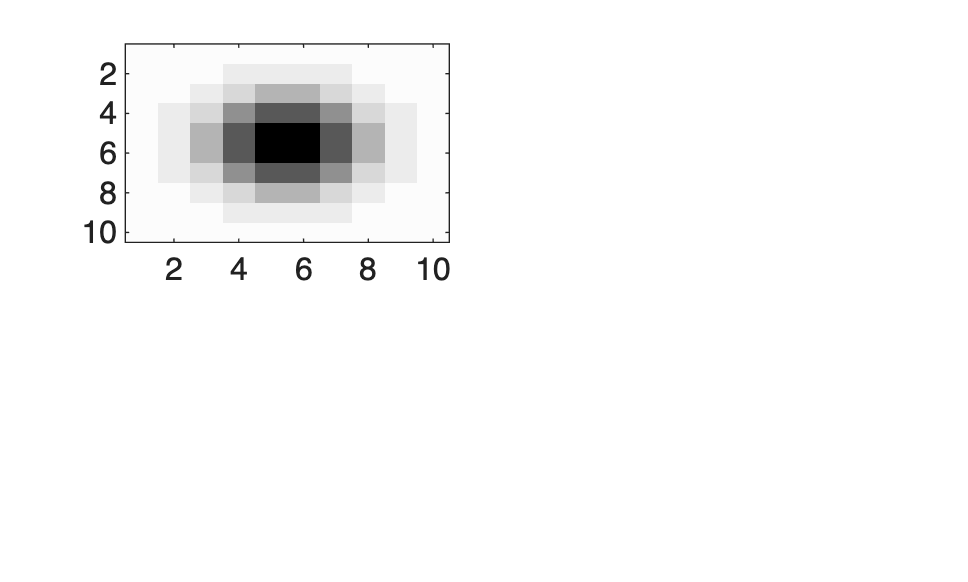


% plot pdf and confidence interval
figure(1)
subplot(2,2,1)
c=linspace(0.99,0.0,64)';
C=[c,c,c];
imagesc(Fc)
colormap(C);
set(gca,'FontSize',12)

## Noisy field

add noise

subplot(2,2,2)
rng(0)
F2=F+normrnd(0,1,10,10);
F2c=uint8(F2)

F2c = 10×10 uint8 matrix
    1    0    1    1    0    0    0    0    1    0
    2    3    0    0    1    1    1    1    0    0
    0    1    2    1    4    3    3    1    0    1
    1    1    4    5    9    8    7    3    2    3
    0    2    4    6   13   14   11    3    0    0
    0    1    5   11   14   16    9    2    2    0
    0    1    3    6    9    8    4    1    1    0
    0    2    1    2    4    4    2    1    0    0
    4    1    1    2    2    1    0    0    0    0
    3    1    0    0    1    1    2    0    0    0


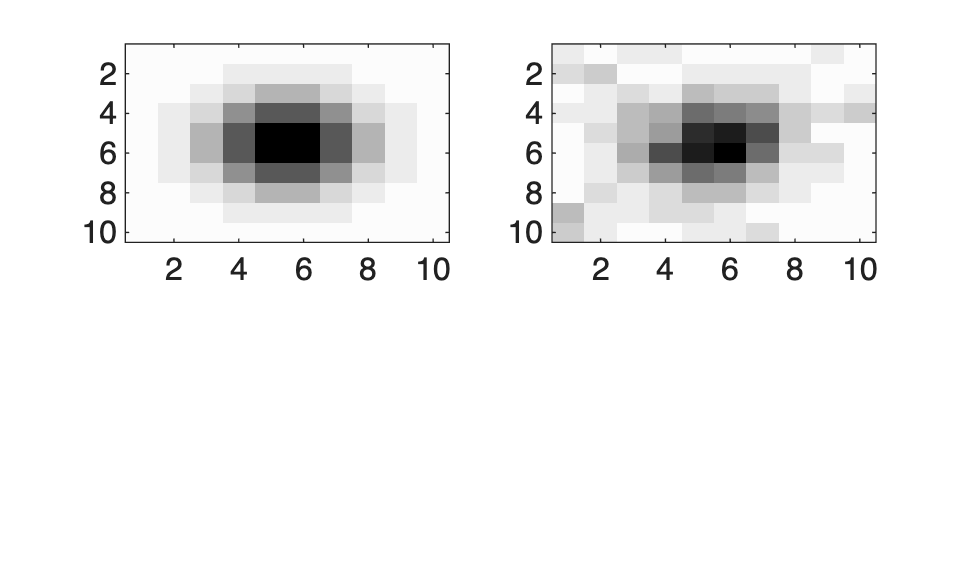

imagesc(F2c)
colormap(C);
set(gca,'FontSize',12)

print -depsc ch6_image_field.eps

## Rank and SVD

compute rank of matrices

rank(double(Fc))

ans = 4

rank(double(F2c))

ans = 10


% compute SVD of matrices
[U,S,V]=svd(double(Fc));

% compute SVD of matrices
[U2,S2,V2]=svd(double(F2c));

% compute rank-1 approximation of Fc  
D=U(:,1:1)*S(1:1,1:1)*V(:,1:1)'

D =          0         0         0         0         0         0         0         0         0         0
         0    0.0866    0.2925    0.7095    1.1025    1.1025    0.7095    0.2925    0.0866         0
         0    0.2925    0.9880    2.3970    3.7247    3.7247    2.3970    0.9880    0.2925         0
         0    0.7095    2.3970    5.8153    9.0364    9.0364    5.8153    2.3970    0.7095         0
         0    1.1025    3.7247    9.0364   14.0416   14.0416    9.0364    3.7247    1.1025         0
         0    1.1025    3.7247    9.0364   14.0416   14.0416    9.0364    3.7247    1.1025         0
         0    0.7095    2.3970    5.8153    9.0364    9.0364    5.8153    2.3970    0.7095         0
         0    0.2925    0.9880    2.3970    3.7247    3.7247    2.3970    0.9880    0.2925         0
         0    0.0866    0.2925    0.7095    1.1025    1.1025    0.7095    0.2925    0.0866         0
         0         0         0         0         0         0         0         0       

D=uint8(D)

D = 10×10 uint8 matrix
    0    0    0    0    0    0    0    0    0    0
    0    0    0    1    1    1    1    0    0    0
    0    0    1    2    4    4    2    1    0    0
    0    1    2    6    9    9    6    2    1    0
    0    1    4    9   14   14    9    4    1    0
    0    1    4    9   14   14    9    4    1    0
    0    1    2    6    9    9    6    2    1    0
    0    0    1    2    4    4    2    1    0    0
    0    0    0    1    1    1    1    0    0    0
    0    0    0    0    0    0    0    0    0    0


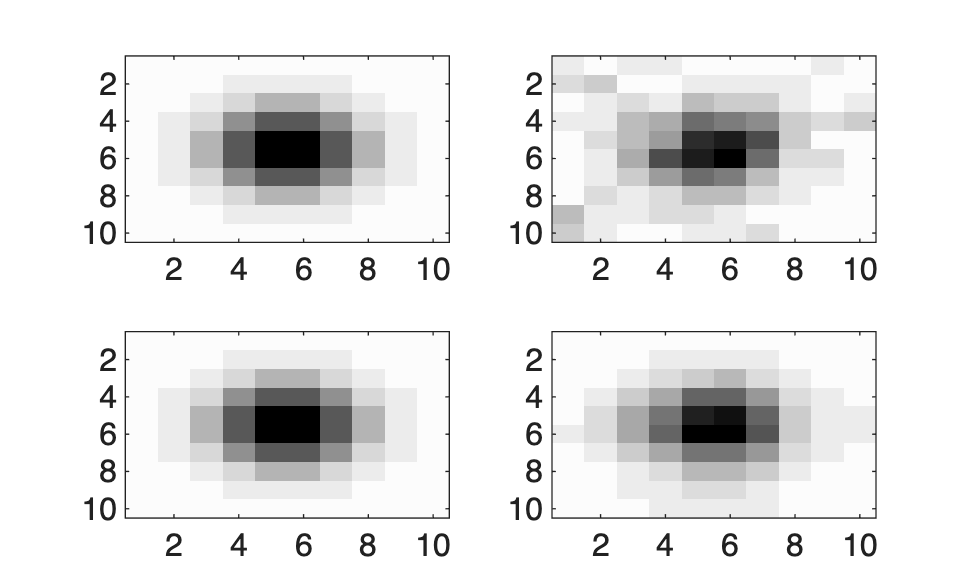

subplot(2,2,3)
imagesc(D)
colormap(C);
set(gca,'FontSize',12)

% compute rank-1 approximation of Fc2  
D2=U2(:,1:1)*S2(1:1,1:1)*V2(:,1:1)';
D2=uint8(D2);
subplot(2,2,4)
imagesc(D2)
colormap(C);
set(gca,'FontSize',12)
print -depsc ch6_svd_matrix_images.eps

## Note

As in the book, eliminating principal components filters out the noise: images can be analyzed as matrices.